# Train Semantic Segmentation on Large Satellite Images

## Introduction

This example walks through the process of:

- Importing a pre-labelled ground truth object

- Modifying the paths of the ground truth to match this training machine

- Converting the large satellite images to blockedImageDatastores

- Building and training, with validation, a semantic segmentation network on blockedImages

- Testing on out of sample data that was not used in the training set.

## Data Usage

The satellite data used in this example is based on SPOT 6/7 Imagery and is reused from the [New South Wales Spatial Data Portal](https://portal.spatial.nsw.gov.au/portal/home/item.html?id=95c0763e95df425abc75ad52e2b35c94) and is licensed under a Creative Commons Attribution 3.0 License with additional acknowledgement to Airbus (CNES (2020) DISTRIBUTION AIRBUS DS) as the original provider of the data to the NSW Government.

clearvars
doTraining = false;

## Load the Ground Truth Data

During this step we have to correct for the data being in different locations from the machine that did the labelling and the machine, here, that is doing the training.

data = load(fullfile("gTruth.mat"));
gTruth = data.gTruth;
% Image data:
basePath = "C:\MATLAB\data\871012_mining\spot67Extract";
alternatePath = fullfile(getProjectRootDir, "dataRaw");
spotPair = [basePath alternatePath];
% Labels
basePath = "C:\MATLAB\data\871012_mining\processed";
alternatePath = fullfile(getProjectRootDir, "dataLabels");
processedPair = [basePath alternatePath];
alternatePaths = {spotPair, processedPair};
unResPaths = changeFilePaths(gTruth, alternatePaths)


unResPaths = 

  0×0 empty string array



clear data

## Build the blockedLabelDatastores

[imds,pxds] = pixelLabelTrainingData(gTruth);
patchSize = [296,296,3];
normalStrideFactor = 0.5;

### Convert imds to blockedimagedatastore

Convert the ground truth imageDatastore into a blockedImageDatastore.

bim = [];
for ii = 1:numel(imds.Files)
    bim = [bim; ...
        blockedImage(imds.Files(ii))]; %#ok<AGROW> 
end
blkProperties = selectBlockLocations(bim, ...
    "BlockSize",patchSize(1:2),...
    "BlockOffsets", floor(patchSize(1:2) * normalStrideFactor), ...
    "InclusionThreshold",0.75,...
    "ExcludeIncompleteBlocks",true);
blkIMDSImgs = blockedImageDatastore(imds.Files, ...
    "BlockLocationSet", blkProperties);

### Convert pixellabeldatastore to blockimage

Similarly we have to convert the pixel labels to categorical arrays required for semantic segmentation

biml = [];
for ii = 1:numel(pxds.Files)
    biml = [biml; ...
        blockedImage(pxds.Files(ii))]; %#ok<AGROW> 
end
blkProperties = selectBlockLocations(biml, ...
    "BlockSize",patchSize(1:2),...
    "BlockOffsets", floor(patchSize(1:2) * normalStrideFactor), ...
    "InclusionThreshold",0.75,...
    "ExcludeIncompleteBlocks",true);
blkIMDSLbls = blockedImageDatastore(pxds.Files, ...
    "BlockLocationSet", blkProperties);
blkIMDSLblsCats = transform(blkIMDSLbls,...
    @(bs){categorical(bs{1}, [1,2], pxds.ClassNames)});

### Split into Test/Train/Validate Sections

trainValTestSplit = [0.6 0.9 1.0];
nBlocks = blkIMDSImgs.TotalNumBlocks;
selectIDX = randperm(nBlocks)';
% Train
idxTrain = selectIDX(1:floor(trainValTestSplit(1) * nBlocks));
blkIMDSImgsTrain = subset(blkIMDSImgs, idxTrain);
blkIMDSLblsCatsTrain = subset(blkIMDSLblsCats, idxTrain);

% Validate
idxVal   = selectIDX(floor(trainValTestSplit(1) * nBlocks)+1:floor(trainValTestSplit(2) * nBlocks));
blkIMDSImgsVal = subset(blkIMDSImgs, idxTrain);
blkIMDSLblsCatsVal = subset(blkIMDSLblsCats, idxTrain);

% Test
idxTest = selectIDX(floor(trainValTestSplit(2) * nBlocks)+1:end);
blkIMDSImgsTest = subset(blkIMDSImgs, idxTest);
blkIMDSLblsCatsTest = subset(blkIMDSLblsCats, idxTest);

### Combine Datastores Ready for Training

dataTrain = combine(blkIMDSImgsTrain, blkIMDSLblsCatsTrain);
dataVal = combine(blkIMDSImgsVal, blkIMDSLblsCatsVal);
dataTest = combine(blkIMDSImgsTest, blkIMDSLblsCatsTest);

### Plots to Check

#### Full Size Image

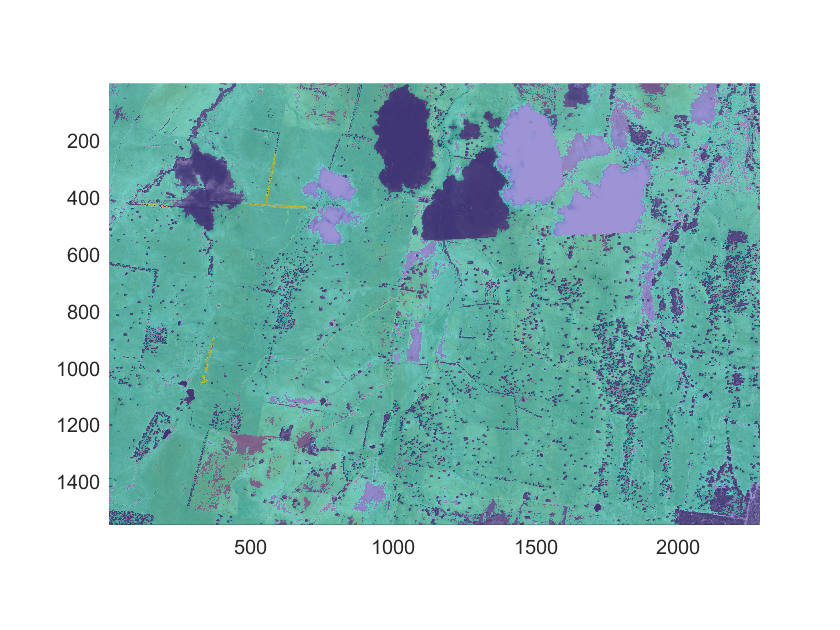

figure
hbim = bigimageshow(bim(1));
showlabels(hbim,biml(1),Colormap=parula(numel(pxds.ClassNames)+1))

#### Grab a Sub-Block Image

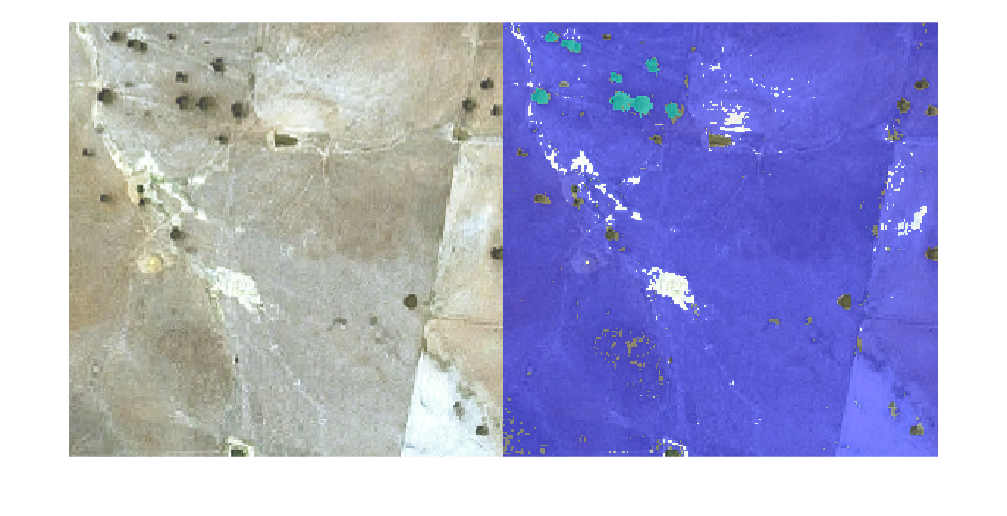

figure
data = read(dataTrain);
A = data{1};
B = labeloverlay(data{1}, data{2});
montage(cat(4, A, B), [1, 2])

reset(dataTrain)

## Create a Semantic Segmentation Network

Create a simple semantic segmentation network and learn about common layers found in many semantic segmentation networks. A common pattern in semantic segmentation networks requires the downsampling of an image between convolutional and ReLU layers, and then upsample the output to match the input size. This operation is analogous to the standard scale-space analysis using image pyramids. During this process however, a network performs the operations using non-linear filters optimized for a specific set of classes that you want to segment.

### Create An Image Input Layer

A semantic segmentation network starts with an imageInputLayer, which defines the smallest image size the network can process.

imgLayer = imageInputLayer(patchSize)

imgLayer =   ImageInputLayer with properties:

                      Name: ''
                 InputSize: [296 296 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: []


### Create Downsampling Network

Start with the convolution and ReLU layers. The convolution layer padding is selected such that the output size of the convolution layer is the same as the input size. This makes it easier to construct a network because the input and output sizes between most layers remain the same as you progress through the network.

filterSize = 3;
numFilters = 32;
conv = convolution2dLayer(filterSize,numFilters,'Padding',1);
relu = reluLayer();

The downsampling is performed using a max pooling layer. Create a max pooling layer to downsample the input by a factor of 2 by setting the 'Stride' parameter to 2.

poolSize = 2;
maxPoolDownsample2x = maxPooling2dLayer(poolSize,'Stride',2);

Stack the convolution  ReLU, and max pooling layers to create a network that downsamples its input by a factor of 4.

downsamplingLayers = [
    conv
    relu
    maxPoolDownsample2x
    conv
    relu
    maxPoolDownsample2x
    ]

downsamplingLayers =   6×1 Layer array with layers:

     1   ''   Convolution   32 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     2   ''   ReLU          ReLU
     3   ''   Max Pooling   2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     4   ''   Convolution   32 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     5   ''   ReLU          ReLU
     6   ''   Max Pooling   2×2 max pooling with stride [2  2] and padding [0  0  0  0]

### Create Upsampling Network

The upsampling is done using the tranposed convolution layer (also commonly referred to as "deconv" or "deconvolution" layer). When a transposed convolution is used for upsampling, it performs the upsampling and the filtering at the same time.

Create a transposed convolution layer to upsample by 2.

filterSize = 4;
transposedConvUpsample2x = transposedConv2dLayer(4,numFilters,'Stride',2,'Cropping',1);

The 'Cropping' parameter is set to 1 to make the output size equal twice the input size.

Stack the transposed convolution and relu layers. An input to this set of layers is upsampled by 4.

upsamplingLayers = [
    transposedConvUpsample2x
    relu
    transposedConvUpsample2x
    relu
    ]

upsamplingLayers =   4×1 Layer array with layers:

     1   ''   Transposed Convolution   32 4×4 transposed convolutions with stride [2  2] and cropping [1  1  1  1]
     2   ''   ReLU                     ReLU
     3   ''   Transposed Convolution   32 4×4 transposed convolutions with stride [2  2] and cropping [1  1  1  1]
     4   ''   ReLU                     ReLU

### Create A Pixel Classification Layer

The final set of layers are responsible for making pixel classifications. These final layers process an input that has the same spatial dimensions (height and width) as the input image. However, the number of channels (third dimension) is larger and is equal to number of filters in the last transposed convolution layer. This third dimension needs to be squeezed down to the number of classes we wish to segment. This can be done using a 1-by-1 convolution layer whose number of filters equal the number of classes, e.g. 3.

Create a convolution layer to combine the third dimension of the input feature maps down to the number of classes.

numClasses = numel(pxds.ClassNames);
conv1x1 = convolution2dLayer(1,numClasses);

Following this 1-by-1 convolution layer are the softmax and pixel classification layers. These two layers combine to predict the categorical label for each image pixel.

finalLayers = [
    conv1x1
    softmaxLayer()
    pixelClassificationLayer()
    ]

finalLayers =   3×1 Layer array with layers:

     1   ''   Convolution                  2 1×1 convolutions with stride [1  1] and padding [0  0  0  0]
     2   ''   Softmax                      softmax
     3   ''   Pixel Classification Layer   Cross-entropy loss 

### Stack All Layers

Stack all the layers to complete the semantic segmentation network.

net = [
    imgLayer
    downsamplingLayers
    upsamplingLayers
    finalLayers
    ]

net =   14×1 Layer array with layers:

     1   ''   Image Input                  296×296×3 images with 'zerocenter' normalization
     2   ''   Convolution                  32 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   ''   ReLU                         ReLU
     4   ''   Max Pooling                  2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   Convolution                  32 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     6   ''   ReLU                         ReLU
     7   ''   Max Pooling                  2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     8   ''   Transposed Convolution       32 4×4 transposed convolutions with stride [2  2] and cropping [1  1  1  1]
     9   ''   ReLU                         ReLU
    10   ''   Transposed Convolution       32 4×4 transposed convolutions with stride [2  2] and cropping [1 

This network is ready to be trained using trainNetwork from Deep Learning Toolbox™.

## Train

ExecutionEnvironment is set to auto which will use a GPU first, then CPU.  If you have lots of cores and no GPU changing to parallel is a good choice.

opts = trainingOptions('sgdm', ...
    'InitialLearnRate',1e-3, ...
    'MaxEpochs',250, ...
    'MiniBatchSize',64, ...
    'ExecutionEnvironment', 'auto', ...
    'Plots', "training-progress", ...
    'ValidationData', dataVal);
if doTraining
    net = trainNetwork(dataTrain,net,opts);
else
    data = fullfile("semanticSegmentNet.mat");
    net = data.net
    clear data
end

## Test

Test the semantic segmentation network on a sequence of images it has not fully seen before.

dsResults = transform(blkIMDSImgsTest, ...
    @(img)semanticseg(cell2mat(img), net));
metrics = evaluateSemanticSegmentation(dsResults,blkIMDSLblsCatsTest);
confusionchart(table2array(metrics.ConfusionMatrix), ...
    pxds.ClassNames, ...
    "ColumnSummary", "column-normalized", ...
    "RowSummary", "row-normalized")
dataKnow = read(dataTest);
A = labeloverlay(dataKnow{1}, dataKnow{2});
dataLbls = read(dsResults);
dataImg = read(blkIMDSImgsTest);
B = labeloverlay(dataImg{1}, dataLbls); 
montage(cat(4, A, B))

## Save the Model For Future Use

fName = fullfile("semanticSegmentNet.mat");
save(fName, 'net');